clear

options = odeset('RelTol',1e-4, 'Stats','on')

options = struct with fields:
              AbsTol: []
                 BDF: []
              Events: []
         InitialStep: []
            Jacobian: []
           JConstant: []
            JPattern: []
                Mass: []
        MassSingular: []
            MaxOrder: []
             MaxStep: []
         NonNegative: []
         NormControl: []
           OutputFcn: []
           OutputSel: []
              Refine: []
              RelTol: 1.0000e-04
               Stats: 'on'
          Vectorized: []
    MStateDependence: []
           MvPattern: []
        InitialSlope: []


# Уточняющие опции

#### Уравнение Эйлера:


$$\ddot x+\frac{\dot x}{t}+100\frac{x}{t^2}=0,$$
 

где $t \in [1, 100], x(1)=1, \dot x(1)=1.$

Уравнение Эйлера, записанное в виде функции MATLAB:

Решение:

Start_cond = [1; 1];   % Начальные условия
t_interval = [1 5];    % Интервал рассчитываемого времени

2 переменных опции

options_r0  = odeset('Refine', 1, 'Stats','on');
options_r   = odeset('Refine', 100, 'Stats','on');

Решение с `Refine = 1`

[t_r0, X_r0]= ode45(@euler_eqn, t_interval, Start_cond, options_r0); 

25 successful steps
0 failed attempts
151 function evaluations


�

Решение с `Refine = 100`

[t_r, X_r]  = ode45(@euler_eqn, t_interval, Start_cond, options_r);

25 successful steps
0 failed attempts
151 function evaluations


Постройка графиков:

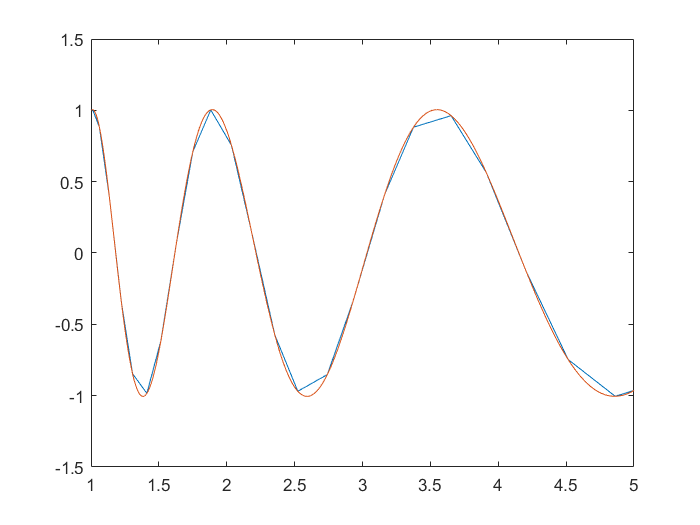

plot(t_r0,X_r0(:,1))
hold on
plot(t_r,X_r(:,1))
hold off

# Определение решения в желаемых точках

**Запишем решение в виде структуры MATLAB:**

Solution = ode45(@euler_eqn, t_interval, Start_cond)

Solution = struct with fields:
     solver: 'ode45'
    extdata: [1×1 struct]
          x: [1 1.0020 1.0119 1.0617 1.1348 1.2239 1.3062 1.4115 1.5150 1.6282 1.7499 1.8821 2.0344 2.1802 2.3543 2.5235 2.7406 2.9301 3.1626 3.3757 3.6528 3.9115 4.2076 4.5152 4.8616 5]
          y: [2×26 double]
      stats: [1×1 struct]
      idata: [1×1 struct]


Зададим вектор желаемых точек:

points = 1.1:0.01:4.2;

Получим решение на векторе:

Eval_result = deval(Solution, points)

Eval_result =     0.6607    0.5895    0.5142    0.4356    0.3542    0.2707    0.1860    0.1006    0.0153   -0.0695   -0.1530   -0.2348   -0.3143   -0.3911   -0.4647   -0.5347   -0.6008   -0.6625   -0.7197   -0.7720   -0.8193   -0.8615   -0.8983   -0.9297   -0.9557   -0.9762   -0.9912   -1.0007   -1.0048   -1.0036   -0.9972   -0.9859   -0.9697   -0.9488   -0.9235   -0.8938   -0.8602   -0.8228   -0.7818   -0.7375   -0.6903   -0.6402   -0.5877   -0.5331   -0.4765   -0.4182   -0.3586   -0.2980   -0.2365   -0.1744
   -6.8853   -7.3331   -7.7096   -8.0149   -8.2499   -8.4158   -8.5141   -8.5469   -8.5165   -8.4258   -8.2777   -8.0758   -7.8240   -7.5261   -7.1857   -6.8069   -6.3937   -5.9501   -5.4799   -4.9873   -4.4760   -3.9499   -3.4127   -2.8679   -2.3191   -1.7696   -1.2225   -0.6809   -0.1474    0.3753    0.8850    1.3794    1.8566    2.3147    2.7520    3.1671    3.5585    3.9253    4.2663    4.5809    4.8686    5.1291    5.3620    5.5673    5.7449    5.8949    6.0175    6.1129    6

Визуализируем результат

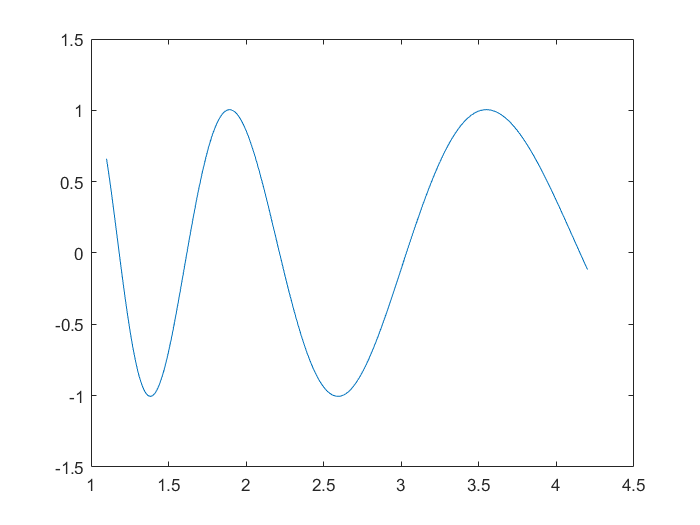

plot(points, Eval_result(1,:))

# Управление шагом решателя

**Зададим опции: **без ограничения шага и с ограничением:

options_ms0 = odeset('Stats','on');
options_ms = odeset('MaxStep',1e-03, 'InitialStep', 1e-04, 'Stats','on');

Получим решения:

[t_ms0, X_ms0] = ode23(@euler_eqn, t_interval, Start_cond, options_ms0);

79 successful steps
8 failed attempts
262 function evaluations


[t_ms, X_ms] = ode23(@euler_eqn, t_interval, Start_cond, options_ms);

4002 successful steps
0 failed attempts
12007 function evaluations


Определим величину шага на каждой итерации:

dt_ms = [t_ms(2:end);0] - t_ms

dt_ms =     0.1000
    0.5000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000


# А нужно ли ограничивать шаг?

**Сравним 3 ситуации: **оценим время вычисления

- Ситуация №1: ограничение шага через **'MaxStep'**

- Ситуация №2: уточнение через `'Refine'`

- Ситуация №3: увеличение точности через  `'AbsTol'` и `'RelTol'`

**Ситуация №1**

options_1 = odeset('MaxStep',1e-05, 'Stats','on');
tic
[t_1, X_1] = ode23(@euler_eqn, t_interval, Start_cond, options_1);

400000 successful steps
0 failed attempts
1.2e+06 function evaluations


toc

Elapsed time is 3.589454 seconds.


**Ситуация №2**

options_2 = odeset('Refine',4000, 'Stats','on');
tic
[t_2, X_2] = ode23(@euler_eqn, t_interval, Start_cond, options_2);

79 successful steps
8 failed attempts
262 function evaluations


toc

Elapsed time is 0.054354 seconds.


**Ситуация №3**

options_3 = odeset('AbsTol',3.8e-17,'RelTol', 3.8e-14, 'Stats','on');
tic
[t_3, X_3] = ode23(@euler_eqn, t_interval, Start_cond, options_3);

261740 successful steps
0 failed attempts
785221 function evaluations


toc

Elapsed time is 2.321139 seconds.
